clearvars

c = (10^-6)/(4 * pi * (8.85418782 * 10^(-12)));

%Pulling x, y, E_x, and E_y from file
Experimental_Data = readtable(['dipole_field100.csv']);

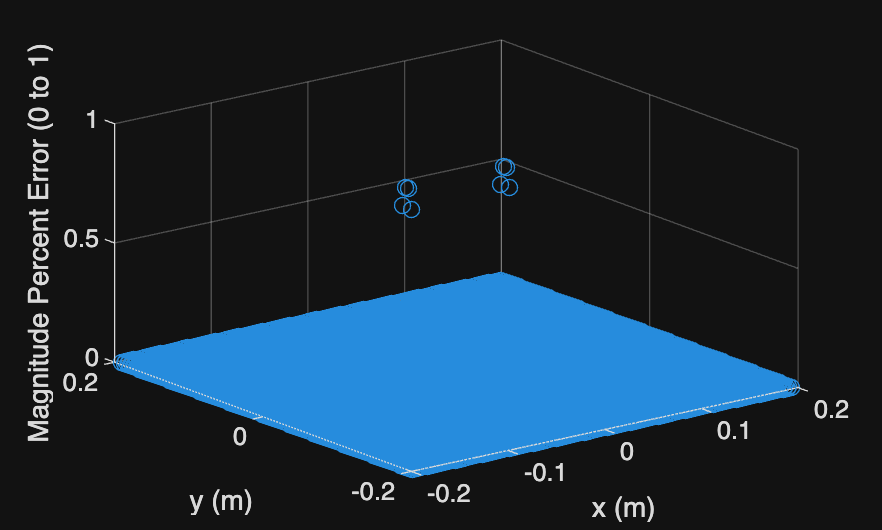

x_e = transpose(Experimental_Data.x_X_m);
y_e = transpose(Experimental_Data.y_m);
Ex_e = transpose(Experimental_Data.Ex_V_per_m);
Ey_e = transpose(Experimental_Data.Ey_V_per_m);

%Calculating analytical electric field
pq_divisor = sqrt((((x_e-0.05).^2) + (y_e.^2)).^3);
nq_divisor = sqrt((((x_e+0.05).^2) + (y_e.^2)).^3);
Ex_a = c * (((x_e-0.05)./(pq_divisor)) - ((x_e+0.05)./(nq_divisor)));
Ey_a = c * (((y_e)./(pq_divisor)) - ((y_e)./(nq_divisor)));

%Calculating electric field angle
if Ex_e > 0
    t_e = atan(Ey_e./Ex_e);
else
    t_e = -1 * atan(Ey_e./Ex_e);
end

if Ex_a > 0
    t_a = atan(Ey_a./Ex_a);
else
    t_a = -1 * atan(Ey_a./Ex_a);
end

%Calculating electric field magnitude
m_e = sqrt((Ex_e.^2) + (Ey_e.^2));
m_a = sqrt((Ex_a.^2) + (Ey_a.^2));

%Calculating Percent Errors
pe_Ex = abs((Ex_a - Ex_e)./(Ex_a));
pe_Ey = abs((Ey_a - Ey_e)./(Ey_a));
pe_m = abs((m_a - m_e)./(m_a));
pe_t = abs((t_a - t_e)./(t_a));


%{
figure(1)
scatter3(x_e, y_e, pe_Ex)
xlabel('x (m)')
ylabel('y (m)')
zlabel('E_x Percent Error (0 to 1)')

figure(2)
scatter3(x_e, y_e, pe_Ey)
xlabel('x (m)')
ylabel('y (m)')
zlabel('E_y Percent Error (0 to 1)')
%}

figure(3)
scatter3(x_e, y_e, pe_m)
xlabel('x (m)')
ylabel('y (m)')
zlabel('Magnitude Percent Error (0 to 1)')

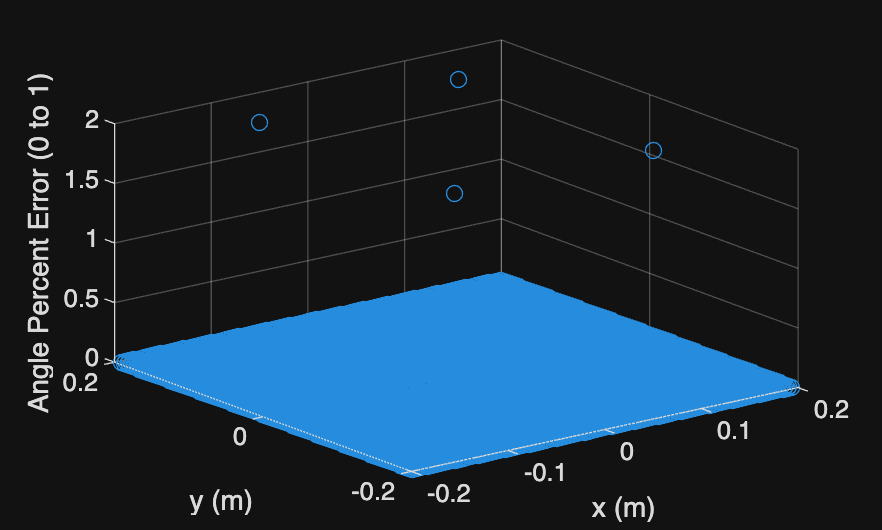


figure(4)
scatter3(x_e, y_e, pe_t)
xlabel('x (m)')
ylabel('y (m)')
zlabel('Angle Percent Error (0 to 1)')